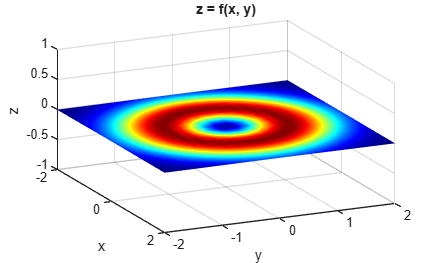

%1a

x = linspace(-2, 2, 20);
y = linspace(-2, 2, 20);

[X, Y] = meshgrid(x, y);

Z = sin((X.^2 + Y.^2)/20) .* exp(-(X.^2 + Y.^2));

figure;
surf(X, Y, Z);

shading interp;
colormap jet;

xlim([-2 2]);
ylim([-2 2]);
zlim([-1 1]);

[az, el] = view;
view(65, el);

title('z = f(x, y)');
xlabel('x');
ylabel('y');
zlabel('z');

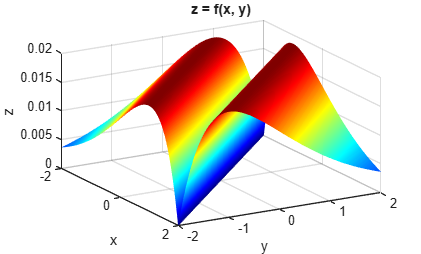

%1b

clear
close all

x = linspace(-2, 2);
y = linspace(-2, 2);

[X, Y] = meshgrid(x, y);

Z = sin(abs(X+Y)/20) .* exp(-abs(X+Y));

figure;
surf(X, Y, Z);

shading interp;
colormap jet;

xlim([-2 2]);
ylim([-2 2]);

[az, el] = view;
view(60, el);

title('z = f(x, y)');
xlabel('x');
ylabel('y');
zlabel('z');

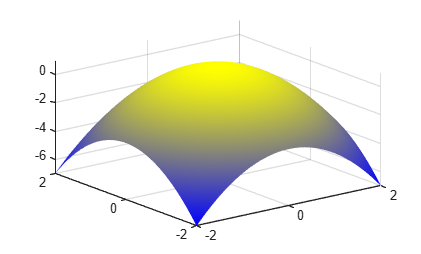

%Papildoma

clear
close all

x = linspace(-2, 2);
y = linspace(-2, 2);

[X, Y] = meshgrid(x, y);

Z = 1 - (X.^2 + Y.^2);

figure;
surf(X, Y, Z);
shading interp;
r1 = linspace(0, 1, 256);
g1 = linspace(0, 1, 256);
b1 = linspace(1, 0, 256);
map1 = [r1', g1', b1'];
colormap(map1);

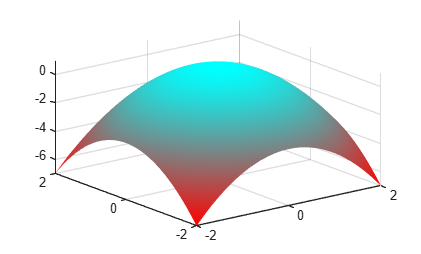


figure;
surf(X, Y, Z);
shading interp;
r2 = linspace(1, 0, 256);
g2 = linspace(0, 1, 256);
b2 = linspace(0, 1, 256);
map1 = [r2', g2', b2'];
colormap(map1);

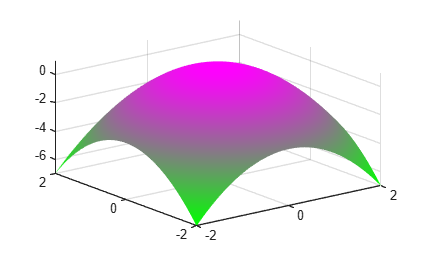


figure;
surf(X, Y, Z);
shading interp;
r3 = linspace(0, 1, 256);
g3 = linspace(1, 0, 256);
b3 = linspace(0, 1, 256);
map1 = [r3', g3', b3'];
colormap(map1);